#  k-d Tree VS Matrix

## Overview

This will be a demonstration of my implementation of a kNN classifer with a k-d tree. We will compare the speed to other models using biopsies and sepal data sets aswell as a dataset I will create.

This will not include what a k-d tree is or any of its functionallity rather this script will be a comparison between my implementation and other implementations. The worksheet will include this information. All classes and functions called in this folder are well documented. Feel free to look there for more information.

## Initialisation of Data and Models

We will initialise 3 different models. The default knn search (matlabs kd tree), my knn search (no kd tree) and finally my knn search with kd tree (my kd tree). Choose from above by uncommenting the lines to use the biopsies dataset or the sepal dataset.

% uncomment this line and comment line below for search on biopsies dataset
% [train_examples,test_examples,train_labels,test_labels] = format_m_data('biopsies',1);

[train_examples,test_examples,train_labels,test_labels] = format_m_data('sepal',3);

Sample of data:

ans = 10×3 cell array
    {'sepal_length'}    {'sepal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {'setosa' }


test_examples size:	 60 2
test_labels size:	 60 1
train_examples size:	 90 2
train_labels size:	 90 1



% fitcknn done in previous labs, uses brute force approach
m_knn = my_fitcknn(train_examples, train_labels);

% my implementation of a k-d tree
m_kd = kd_fitcknn(train_examples, train_labels);

% matlab implementation of a k-d tree
m = fitcknn(train_examples, train_labels);

## Proof of Equal Result to Default

This proves that the k-d tree and default knn search yield the exact same results for any k on any dataset where the defualt search has default hyper parameters. Both models priorities the neighbour with the largest index value in the training data.

n = 10;
noEqualPredictions = zeros(1,n);

for i=1:n
    p_kd = m_kd.predict(test_examples);

    p = m.predict(test_examples);

    noEqualPredictions(i) = sum(p_kd == p)./height(test_examples);
end

% shows the % of how many results are the same across all values of k
% if 1 all values are equal
mean(noEqualPredictions)

ans = 1

## Demonstration of Times

Here we test the times and plot them. As you can see both m_knn and m have a constant time whereas my m_kd has  time that increases based off the number of k. This is because more of the tree must be searched.

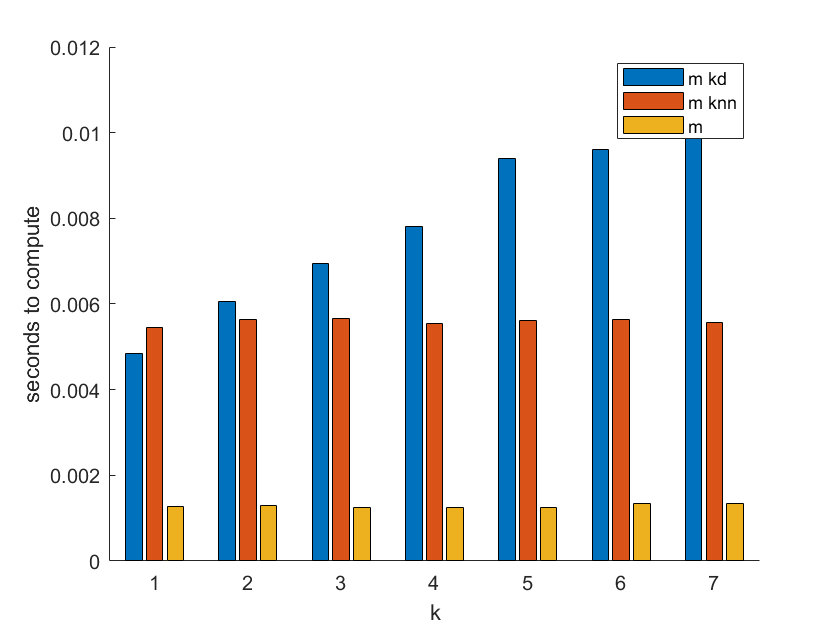

% store sum of matching results from default knn and kd_Tree implementation
n = 7;
timem_kd = zeros(1,n);
timem_knn = zeros(1,n);
timem= zeros(1,n);

% time each prediction and store in appropriate array, change NumNeighbours
% each time
for i=1:1:n
    m_kd.NumNeighbors = i;
    f = @() m_kd.predict(test_examples);
    timem_kd(i) = timeit(f);

    m_knn.NumNeighbors = i;
    f = @() m_knn.predict(test_examples);
    timem_knn(i) = timeit(f);
    
    m.NumNeighbors = i;
    f = @() m.predict(test_examples);
    timem(i) = timeit(f);
end

k = 1:1:n;

% bar graph shows seconds to compute each prediction for each modle for each value of k. 
% different models are shown as different colours, blue is my kd, red is my
% brute force and orange is matlabs
figure;
xlabel('k')
ylabel('seconds to compute')
hold('on')
bar(k,[timem_kd;timem_knn;timem])
legend('m kd','m knn','m')
hold('off')

From this data we can conclude that the overhead for searching the tree is far too expencive for datasets that are not very large like biopsies and sepal.

## Making Large DataSet

In this section we will make a very large dataset and compare the times of the kd tree and the brute force knn modle. We will be using 2 features (dimentions) as our large dataset as k-d trees peform better will smaller number of dimentions.

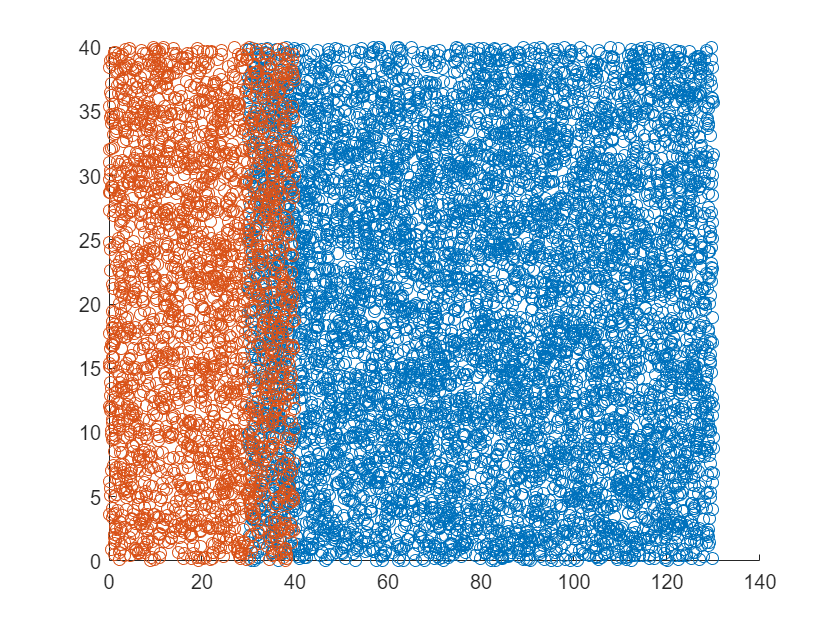

rng(0)

% data will have 2 features, and 10k observations
data = rand(10000,2);
% we will make a slight trend where data with x < 40 is classA and x > 40 is class B
data(1:7500) = data(1:7500) * 100 + 30;
data(7501:end) = data(7501:end) * 40;

% visual representation
figure;
hold('on')
scatter(data(1:7500,1),data(1:7500,2))
scatter(data(7501:end,1),data(7501:end,2))
hold('off')


% make labels
labels = categorical;
labels(1:7500,1) = "A";
labels(7501:10000,1) = "B";

% randomise data
myi = randperm(10000);
data = data(myi,:);
labels = labels(myi,:);

% make training and testing data
train_examples = data(1:6000,:);
test_examples = data(6001:end,:);

train_labels = labels(1:6000,:);
test_labels= labels(6001:end,:);


## Testing Large DataSet

Here we time the setup of the models and the search time of the models. The k-d tree should have a O(log(n)) time complexity for search whereas the brute force should have a O(n). The k-d tree should perform much better than the brute force aproach here.

n = 1;

% fitcknn done in previous labs, uses brute force approach
tic
m_knn = my_fitcknn(train_examples, train_labels);
toc 

Elapsed time is 0.003030 seconds.



% my implementation of a k-d tree
tic
m_kd = kd_fitcknn(train_examples, train_labels);
toc

Elapsed time is 0.068727 seconds.



% timing how long predict takes for each model
% THIS WILL TAKE A LONG TIME
m_kd.NumNeighbors = 1;
f = @() m_kd.predict(test_examples);
timem_kd = timeit(f);

m_knn.NumNeighbors = n;
f = @() m_knn.predict(test_examples);
timem_knn = timeit(f);

timem_kd
timem_knn


## Recursion vs Itteration in Matlab

Below we have 4 methods, recursion using both a property and argument to itterate and loops to itterate using a property and an argument. Run the program to see the times.

test = testClass();

% recursion with property incrementing
f = @() test.recProp;
timeit(f)

% recursion with argument incrementing
f = @() test.recArg(0);
timeit(f)

% while loop with property incrementing
f = @() test.incProp();
timeit(f)

% for loop with variable incrementing
f = @() test.incVar();
timeit(f)


This explains why my k-d tree is so slow. It is too dependant on recursion to run in matlab specifically. Other languages would not have such issues. After speaking to Ryan Cunningham he sudjested that interpreted languages are much slower at recursion, a big example of this is python.

## My vs Matlabs Implementation

After reading the source code for matlabs kd_Tree`Searcher` I will compare the implementation of mine vs matlabs.

Each node in my k-d tree holds a value whereas matlabs k-d tree opperates more like a binary tree where each node asks a question and does not hold a value. The values in matlabs tree are only stored in the leaf nodes which are different to regular nodes.

Matlabs leaf nodes hold a pre defined number of observations. This is called the bucket size, at default it is set to 50.

I have modeled my nodes as objects whereas matlab has not. Matlab has modeled the observations and nodes as elements in a matrix (who could have guessed) as this is much faster for the language.

Finally in order to search my tree I used recursion as it seemed the most natural approch whereas Matlab used a standard loop which is also alot faster for the language as discussed above.

## Conclusion

From this study we can say that the current implementation of my k-d tree is not ideal for small datasets and actually increases the searchtime for large values of k vs a brute force approach. In the next implementation I will take into consideration the difference between my implementation and Matlabs and will use 